%%% Define baseline parameters:
rho_outer = 0.08;
rho_inner = 0.015;

% Actuator position radii and the associated moment-arm matrix
rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
    1, 1, 1, 1;
    0, 0, 0, 0;
    -rhos;
    ];

l_0 = 0.5;

g_0 = Pose2.hat([0, 0, -pi/2]);
N_nodes = 10;

% Assemble it all into structs
struct_design_base = struct();
struct_design_base.mat_A = mat_A;
struct_design_base.rhos = rhos;
struct_design_base.l_0 = l_0;
struct_design_base.g_0 = g_0;

% Muscle force functions
f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;

%%% Create variations 
struct_antagonist = struct_design_base;
struct_antagonist.fs = {f_bellow, f_muscle, f_muscle, f_bellow};
struct_antagonist.p_bounds = [50; 100; 100; 50];

struct_4muscle= struct_design_base;
struct_4muscle.fs = {f_muscle, f_muscle, f_muscle, f_muscle};
struct_4muscle.p_bounds = [100; 100; 100; 100];

struct_4bellow= struct_design_base;
struct_4bellow.fs = {f_bellow, f_bellow, f_bellow, f_bellow};
struct_4bellow.p_bounds = [50; 50; 50; 50];

arm_designs = {struct_4bellow, struct_antagonist};
N_designs = numel(arm_designs);

%%% Generate the test shape

f_affine_curvature = @(s, a, b) [
    l_0*ones(size(s)); % TODO: This seems suspect - but for these tests it's really hard to consider what this should be
    zeros(size(s));
    a*s + b
];

s = linspace(0, 1, N_nodes);
segment_twists = f_affine_curvature(s, -3, 3);

%%% Compute the attainable wrench space
cell_bndries_af = cell(1, N_designs);
cell_bndries_am = cell(1, N_designs);

for i = 1 : N_designs
    [cell_bndries_af{i}, cell_bndries_am{i}] = calc_attainable_wrench_hull(segment_twists, arm_designs{i});
end

%%% Sample external loads and compute the corresponding externally-induced
%%% wrenches
% First we generate the tip loads
F_x_scale = 20;
F_y_scale = 20;
tau_scale = 5;
K_scales = diag([F_x_scale, F_y_scale, tau_scale]);

rng(100);
N_test_ws = 100;
w_tip_tests = K_scales* (rand(3, N_test_ws) - 0.5);
mat_s_w_samples = repmat(s, [N_test_ws, 1]);

% For each tip load, compute the corresponding loads that they induce 
% at each point along the lengths of each above arm

all_a_req_traces_f = zeros(N_nodes, N_test_ws);
all_a_req_traces_m = zeros(N_nodes, N_test_ws);

ws= zeros(3, N_nodes, N_test_ws);
    
for i_test = 1 : N_test_ws
    w_tip_i = w_tip_tests(:, i_test);
    ws(:, :, i_test) = calc_external_wrench(segment_twists, w_tip_i, g_0);
end
    
[all_a_req_traces_f, all_a_req_traces_m] = mat_wrenches_to_traces(-ws);

%%% For each arm design: for each tip load, find the attainable arm shape
%%% that is closest to the target shape
min_residuals_all = zeros(N_designs, N_test_ws);
p_solns = zeros(4, N_test_ws, N_designs);
tic
for i_design = 1 : N_designs
    design_to_test = arm_designs{i_design};
    [min_residuals_all(i_design, :), p_solns(:, :, i_design)] = ...
        test_attainability_across_loads(w_tip_tests, segment_twists, design_to_test);
    
    % Compute the attainability of each tip-load at the shape using
    % check_reactions_attainable 
end

toc

Elapsed time is 208.507379 seconds.


% Compute all of the equilibrium poses from the above arm designs and test
% loads. Afterwards we can just directly index from here and skip the
% hassel
tic
cell_closest_poses = cell(N_designs, N_test_ws);
cell_closest_twists = cell(N_designs, N_test_ws);
for i_design = 1 : N_designs
    for i_load = 1 : N_test_ws
        cell_closest_twists{i_design, i_load} = solve_equilibrium_shape(N_nodes, arm_designs{i_design}, p_solns(:, i_load, i_design), w_tip_tests(:, i_load));
        cell_closest_poses{i_design, i_load} = calc_poses(g_0, cell_closest_twists{i_design, i_load});
    end
end
toc

Elapsed time is 121.671298 seconds.


% Then rank the tip-loads by their associated attainability.
min_residuals_sorted = zeros(size(min_residuals_all));
p_solns_sorted = zeros(size(p_solns));

for i_design = 1 : N_designs
    [~, i_sort] = sort(min_residuals_all(i_design, :));
    min_residuals_sorted(i_design, :) = min_residuals_all(i_design, i_sort);
    p_solns_sorted(:, :, i_design) = p_solns(:, i_sort, i_design);
end

% Alternatively, rank the tip-loads by how enclosed they are by the
% attainable wrench hull
attainability_of_loads = zeros(N_designs, N_test_ws);
for i_design = 1 : N_designs
    loads_attainable_i = check_loads_attainable(cell_bndries_af{i_design}, cell_bndries_am{i_design}, all_a_req_traces_f, all_a_req_traces_m);
    attainability_of_loads(i_design, :) = sum(loads_attainable_i, 1);
end

N_to_plot = 10;
% Take the tip loads with top X percentile attainability according to the
% enclosure test.

## PLOTTING

color_green = [45 182 125] / 255;
color_yellow = [255 176 0] / 255;
color_blue = [100 143 255] / 255;
color_red = [255 48 150] / 255;
colors = [color_red; color_blue; color_yellow];

% Lighter colors
colors_light_green = [130 205 174] / 255;
colors_light_yellow = [248 203 97] / 255;
colors_light_blue = [135 167 250] / 255;
colors_light_red = [230 100 164] / 255;
colors_light = [colors_light_red; colors_light_blue; colors_light_yellow];

% Darker colors
color_dark_green = [0.0706    0.5137    0.3294];
color_dark_blue = [0.2941    0.4196    0.7490];
color_dark_yellow = [0.7490    0.5176         0];
color_dark_red = [0.6549    0.1059    0.3725];
colors_dark = [color_dark_red; color_dark_blue; color_dark_yellow];

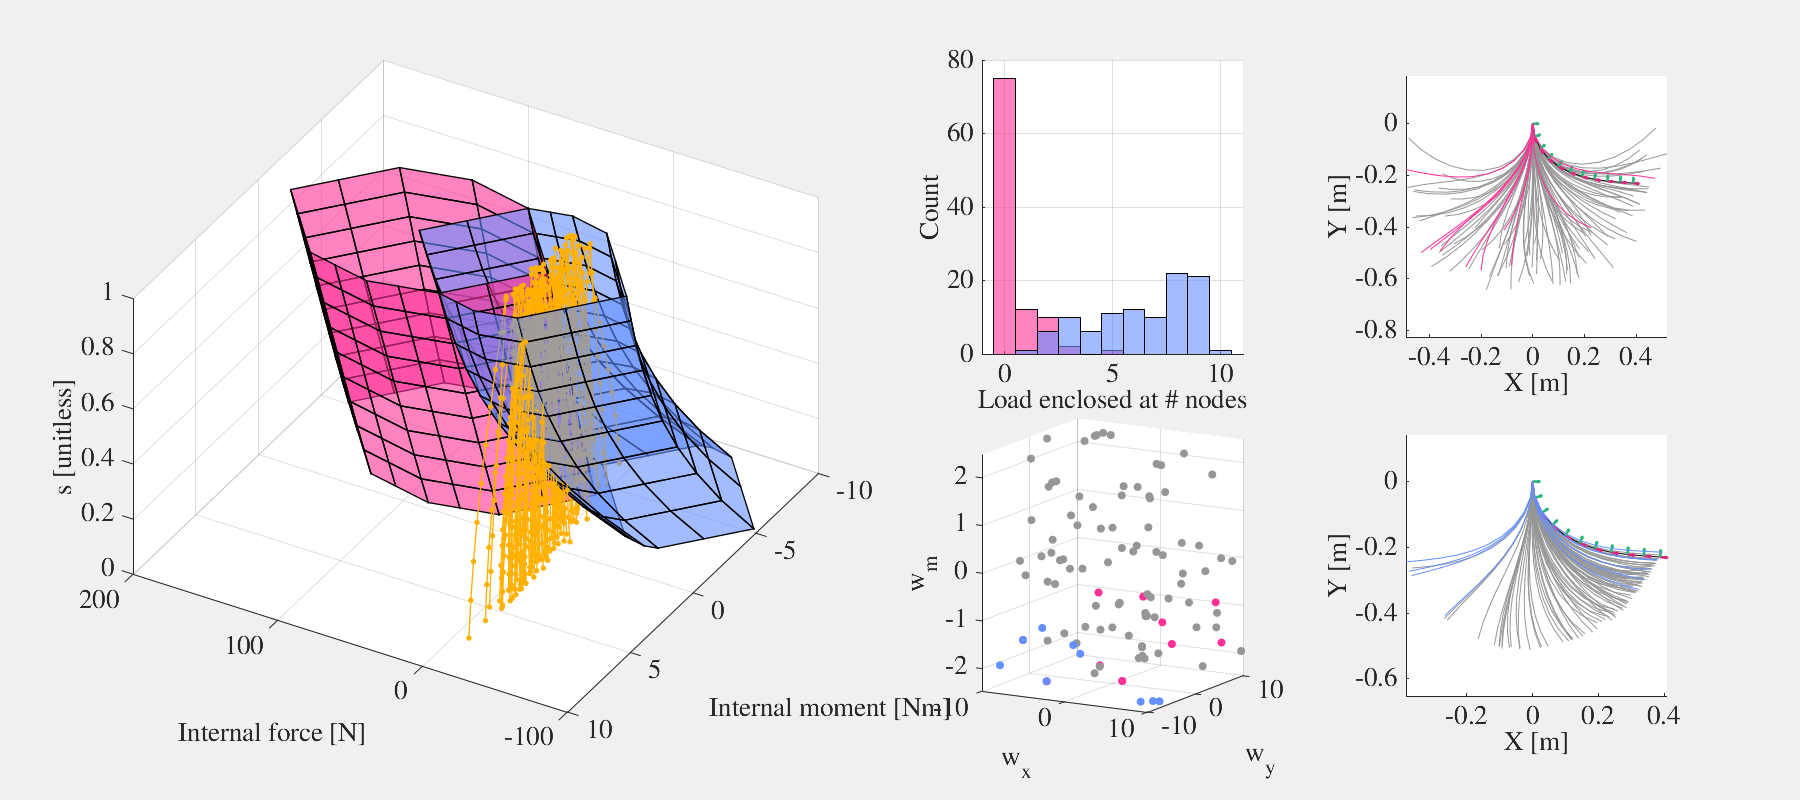

figure("Visible", true, "Position", [0, 0, 1800, 800])
t = tiledlayout(2, 4, "TileIndexing", "columnmajor", "Tilespacing", "compact");

% Plot 1: Comparison of the attainable wrench hulls of the bellows-only and
% antagonistic designs.
ax = nexttile([2, 2]);
hold on
for i = 1 : N_designs
    plot_wrench_hull(cell_bndries_af{i}, cell_bndries_am{i}, ax, colors(i, :));
end
plot3(all_a_req_traces_f, all_a_req_traces_m, mat_s_w_samples', "o-", "color", color_yellow, "markerfacecolor", color_yellow, "markersize", 3, "linewidth", 1)
view(-150, 45);
grid on;
xlabel("Internal force [N]")
ylabel("Internal moment [Nm]")
zlabel("s [unitless]")

ax = nexttile([1, 1]);
hold on
for i = 1 : N_designs
    histogram(attainability_of_loads(i, :), "facecolor", colors(i, :))
end
xlabel("Load enclosed at # nodes")
ylabel("Count")
grid on

ax = nexttile([1, 1]);
N_to_plot = 10;

hold on
plotted = false(1, N_test_ws);
for i = 1 : N_designs
    [~, i_sort] = sort(attainability_of_loads(i, :));
    w_tip_tests_sorted = w_tip_tests(:, i_sort);
    scatter3(w_tip_tests_sorted(1, 1:N_to_plot), w_tip_tests_sorted(2, 1:N_to_plot), w_tip_tests_sorted(3, 1:N_to_plot), [], colors(i, :), "filled")
    plotted(i_sort(1:N_to_plot)) = true;
end
scatter3(w_tip_tests(1, ~plotted), w_tip_tests(2, ~plotted), w_tip_tests(3, ~plotted), [], [150, 150, 150]/255, "filled");
view(30, 10);
grid on
xlabel("w_x")
ylabel("w_y")
zlabel("w_m")

ax = nexttile([1, 1]);
hold on
poses_target = calc_poses(g_0, segment_twists);
[~, i_sort_1] = sort(attainability_of_loads(1, :), "descend");
for i = N_to_plot+1 : N_test_ws
    closest_poses = cell_closest_poses{1, i_sort_1(i)};
    plot_poses(closest_poses, ax, struct("color", [150, 150, 150] / 255), false);
end
plot_poses(poses_target, ax);
for i = 1 : N_to_plot
    closest_twists = cell_closest_twists{1, i_sort_1(i)};
    closest_poses = cell_closest_poses{1, i_sort_1(i)};
    plot_poses(closest_poses, ax, struct("color", colors(1, :)), false);
end
xlabel("X [m]")
ylabel("Y [m]")


ax = nexttile([1, 1]);
hold on

[~, i_sort_2] = sort(attainability_of_loads(2, :), "descend");

for i = N_to_plot + 1 : N_test_ws
    closest_poses = cell_closest_poses{2, i_sort_2(i)};
    plot_poses(closest_poses, ax, struct("color", [150, 150, 150] / 255), false);
end
plot_poses(poses_target, ax);
for i = 1 : N_to_plot
    closest_twists = cell_closest_twists{2, i_sort_2(i)};
    closest_poses = cell_closest_poses{2, i_sort_2(i)};
    plot_poses(closest_poses, ax, struct("color", colors(2, :)), false);
end
xlabel("X [m]")
ylabel("Y [m]")


fontname("Nimbus roman")
fontsize(20, "points")


% Plot all the pressures in pressure space. Highlight which ones are fully
% enclosed by blue, and fully enclosed by red.

[~, i_sort] = sort(min_residuals);
Q_sorted = w_tip_tests(:, i_sort);

% Check the sorted tip loads - does the sorting classify them in a sensible
% way in the wrench space?
figure("visible", true)
hold on;
scatter3(w_tip_tests(1, :), w_tip_tests(2, :), w_tip_tests(3, :), [], [150, 150, 150]/255, "filled");
scatter3(Q_sorted(1, 1:25), Q_sorted(2, 1:25), Q_sorted(3, 1:25),[], color_yellow, "filled");
scatter3(Q_sorted(1, 1:12), Q_sorted(2, 1:12), Q_sorted(3, 1:12),[], color_blue, "filled");
legend("All", "Closest half", "Closest quartile");
xlabel("f_x")
ylabel("f_y")
zlabel("m")
view(68, 28);
grid on

% It appears that there is some merit here. Let us see what the closest
% solutions are. 
p_solns_sorted = p_solns(:, i_sort);

ax = axes(figure("Visible", true));
% Plot the requirement
pose_requirement = calc_poses(g_0, cell_segment_twists{1});
plot_poses(pose_requirement, ax);

% Plot the top 50%
i_cutoff = round(N_test_ws/10);
for i = 1 : i_cutoff
    segment_twists_i = solve_equilibrium_shape(N_nodes, design_to_test, p_solns_sorted(:, i), Q_sorted(:, i));
    poses_i = calc_poses(g_0, segment_twists_i);
    plot_poses(poses_i, ax, struct("color", color_blue), false);
end
for i = i_cutoff + 1 : N_test_ws
    segment_twists_i = solve_equilibrium_shape(N_nodes, design_to_test, p_solns_sorted(:, i), Q_sorted(:, i));
    poses_i = calc_poses(g_0, segment_twists_i);
    plot_poses(poses_i, ax, struct("color", [150, 150, 150] / 255), false);
end

segment_twists_across_loads_sorted = zeros(3, N_nodes, N_test_ws);
for i = 1 : N_test_ws
    segment_twists_across_loads_sorted(:, :, i) = solve_equilibrium_shape(N_nodes, design_to_test, p_solns_sorted(:, i), Q_sorted(:, i));
end

plot_poses(calc_poses(g_0, segment_twists_across_loads_sorted(:, :, 1)), axes(figure()));
check_equilibrium_norm_modified(segment_twists_across_loads_sorted(:, :, 1), Q_sorted(:, 1), p_solns_sorted(:, 1), design_to_test)
check_equilibrium(segment_twists_across_loads_sorted(:, :, 1), Q_sorted(:, 1), p_solns_sorted(:, 1), design_to_test)
check_equilibrium_norm_modified(segment_twists_across_loads_sorted(:, :, 4), Q_sorted(:, 4), p_solns_sorted(:, 4), design_to_test)
check_equilibrium(segment_twists_across_loads_sorted(:, :, 4), Q_sorted(:, 4), p_solns_sorted(:, 4), design_to_test)

function residuals_out = check_equilibrium_norm_modified(segment_twists, w_tip, pressure, struct_design)
    
    % I'm not sure why q_test is directly implemented as an
    % external-wrench-along-arm value, rather than just the tip wrench.
    %
    % Before tracking down why that is, I'm just going to work with a
    % modified version of the function here.

    residuals = check_equilibrium(segment_twists, w_tip, pressure, struct_design);

    weights_stretch_vs_bending = [1, 1, 10];
    weighted_residuals = diag(weights_stretch_vs_bending) * residuals;

    %dist = norm(weighted_residuals(:));
    residuals_out = sum(vecnorm(weighted_residuals, 1));
end

function [min_residuals, p_solns] = test_attainability_across_loads(tip_loads, segment_twists, struct_design)
    % Check if the reactions induced by a tip load are actually attainable by an arm
    % Inputs:
    %   - w_tip (3 x N_tests): wrench vector representing the tip load.
    %   - segment_twists (3 x N_segments): twist vector at each segment
    %   - struct_design (struct): standard arm design struct
    %   - p_bounds (N_actuators x 1): max pressures for each actuator
    %
    % Outputs:
    %   - v_attainable (N_test_points x 1): boolean vector indicating
    %   whether each test arm reaction requirements are attainable
    N_tests = size(tip_loads, 2);
    N_actuators = length(struct_design.p_bounds);

    min_residuals = zeros(N_tests, 1);
    p_solns = zeros(length(struct_design.p_bounds), N_tests);

    N_starts = 5;
    v_zero = zeros(N_actuators, 1);
    start_points = diag(struct_design.p_bounds) * rand([N_actuators, N_starts - 2]);
    start_points = [start_points, v_zero, struct_design.p_bounds];

    for i = 1 : N_tests
        % Define the cost function: for each pressure, find how close it
        % gets the reactions to those required.
        
        f_reaction_dist = @(pres) check_equilibrium_norm_modified(segment_twists, tip_loads(:, i), pres, struct_design);
        opts = optimoptions('fmincon', 'display', 'off', 'StepTolerance', 1e-20, 'FunctionTolerance', 1e-10); 

        % Solve the optimization problem
        p_soln_starts = zeros(N_actuators, N_starts);
        min_residuals_i = zeros(N_starts, 1);
        for i_start = 1 : N_starts
            p_start = start_points(:, i_start);
            [p_soln_starts(:, i_start), min_residuals_i(i_start), ~, output] = fmincon(f_reaction_dist, p_start, [], [], [], [], v_zero, struct_design.p_bounds, [], opts); 
        end

        % Of the result from each starting point, find the lowest one.
        [min_residuals(i), i_start_min] = min(min_residuals_i);
        p_solns(:, i) = p_soln_starts(:, i_start_min);
    end
end